load set1.dat
load set2.dat

X1 = set1;
X2 = set2;

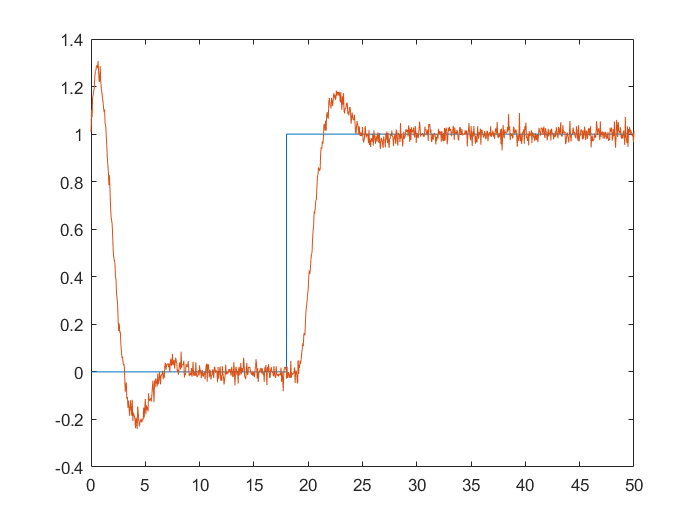

% Plot X1 and X2
% X1 is a step response while X2 is a u(t) - u(t-1) 

plot(X1(:,1),X1(:,2))
hold on
plot(X1(:,1),X1(:,3)) 
hold off

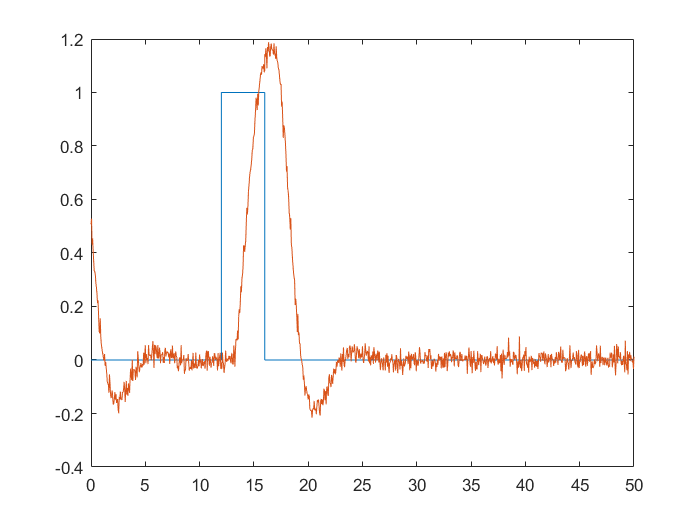

plot(X2(:,1),X2(:,2)) 
hold on
plot(X2(:,1),X2(:,3)) 
hold off

% Estimate transfer function from raw data
np = 1;
nz = 0;
iodelay = 28;

rawdata1 = iddata(X1(:,3), X1(:,2), 1);
rawdata2 = iddata(X2(:,3), X2(:,2), 1);
rawsys1 = tfest(rawdata1,np,nz,iodelay);
rawsys2 = tfest(rawdata2,np,nz,iodelay);

[Y1, W1] = trimLowpass(X1, 301, 550, 0.07, 5);
[Y2, W2] = trimLowpass(X2, 201, 450, 0.07, 5);

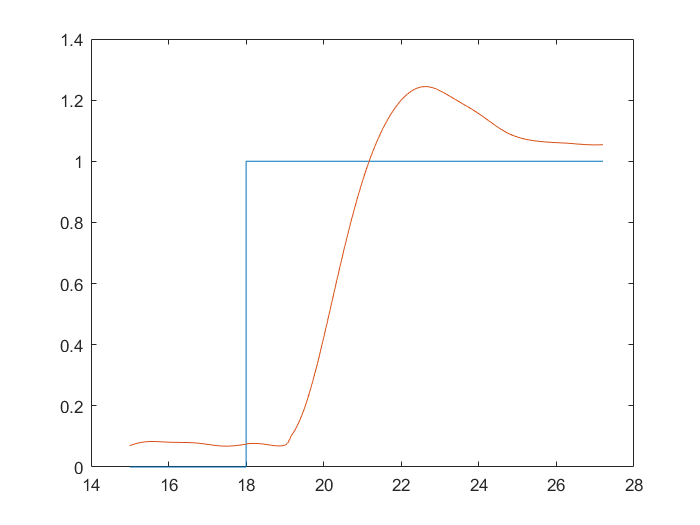

% Plot trimmed and filtered data
plot(Y1(:,1),Y1(:,2))
hold on;
plot(Y1(:,1), W1) % Gives a plot of the input vs. sample number 
hold off;

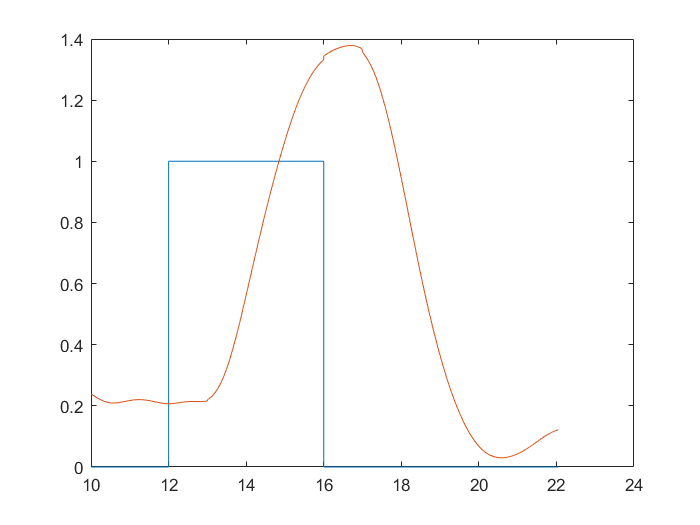


plot(Y2(:,1),Y2(:,2))
hold on;
plot(Y2(:,1), W2) % Gives a plot of the input vs. sample number 
hold off;

data1 = iddata(W1, Y1(:,2), 1);
data2 = iddata(W2, Y2(:,2), 1);
sys1 = tfest(data1,np,nz,iodelay);
sys2 = tfest(data2,np,nz,iodelay);

% Compare transfer functions obtained.
rawsys1

rawsys1 =
 
  From input "u1" to output "y1":
                 0.03826
  exp(-28*s) * -----------
               s + 0.03756
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "rawdata1".
Fit to estimation data: 79.04%                       
FPE: 0.0107, MSE: 0.01063                            


rawsys2

rawsys2 =
 
  From input "u1" to output "y1":
                 0.05296
  exp(-28*s) * -----------
               s + 0.04648
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "rawdata2".
Fit to estimation data: 73.13%                       
FPE: 0.005878, MSE: 0.005843                         


sys1

sys1 =
 
  From input "u1" to output "y1":
                 0.05008
  exp(-28*s) * -----------
               s + 0.04347
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "data1".
Fit to estimation data: 82.9%                     
FPE: 0.00734, MSE: 0.007166                       


sys2

sys2 =
 
  From input "u1" to output "y1":
                  0.053
  exp(-28*s) * -----------
               s + 0.03549
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "data2".
Fit to estimation data: 81.52%                    
FPE: 0.008036, MSE: 0.007846                      
